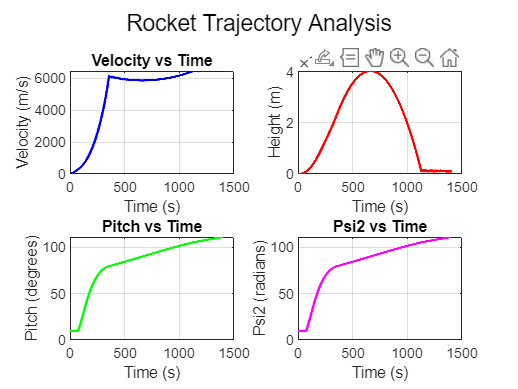

%make sure to be in working directory
%cd 'C:\Users\User\OneDrive - Victoria University of Wellington - STUDENT\B.Thrust Vectoring project\WhatItTakesCode'
clear;

% Load data from CSV file
filename = 'rocket_trajectory.csv';
data = readtable(filename);

% Extract columns
time = data.Time;
velocity = data.Velocity;
height = data.Height;
angle = data.Angle;
psi2 = data.Psi2;
distance = data.Distance; % Directly use the distance column


% Create figure for plots
figure;

% Plot Velocity vs Time
subplot(2,2,1);
plot(time, velocity, '-b', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Velocity (m/s)');
title('Velocity vs Time');
grid on;

% Plot Height vs Time
subplot(2,2,2);
plot(time, height, '-r', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Height (m)');
title('Height vs Time');
grid on;

% Plot Pitch (Angle) vs Time
subplot(2,2,3);
plot(time, angle, '-g', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Pitch (degrees)');
title('Pitch vs Time');
grid on;

% Plot Psi2 vs Time
subplot(2,2,4);
plot(time, psi2, '-m', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Psi2 (radians)');
title('Psi2 vs Time');
grid on;

% Adjust layout
sgtitle('Rocket Trajectory Analysis');

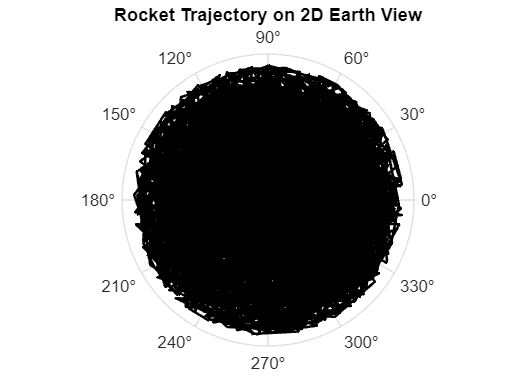



% Create a polar plot for trajectory
figure;
polarplot(height, angle, '-k', 'LineWidth', 1.5);
title('Rocket Trajectory on 2D Earth View');